## Gravitational wave data: first look

We will take a look at a short segment of data from the LIGO Hanford detector. This is the data segment that contains the first detected GW signal, GW150914.

The data file can be obtained from the Gravitational Wave Open Science Center (GWOSC). Data files are provided in the widely used [HDF5 format](https://portal.hdfgroup.org/display/HDF5/Introduction+to+HDF5). 

A single HDF5 file can store multiple types of data as well as information, called attributes, for each type of data. The contents of an HDF5 are organized in a way that is quite similar to a hierarchy of directories and files on a computer. First let us look at the contents of the GW data file.

ls; %List the files in this folder

H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5	readgwoscdat.mlx



You see that an HDF5 file is identified by the extension **.hdf5**.

The file name conveys some basic information about the data including the detector (H1 or LIGO, Hanford), the sampling frequency (4kHz), the start GPS time (1126259447), and the duration (32 sec). Note that all this information is stored within the file itself, so one also save the data under a more convenient file name that's easier to remember.

We can read the GW strain data stored in the file using the following steps.

dataVec = h5read('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain');

The sampling frequency (in Hz) can be obtained using this set of commands.

%Sampling interval
samplIntrvl = h5readatt('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain','Xspacing');
%Sampling frequency
samplFreq = 1/samplIntrvl;
disp(samplFreq);

        4096



We can construct a vector of time samples,

timeVec = (0:(length(dataVec)-1))*samplIntrvl;

and plot the data.

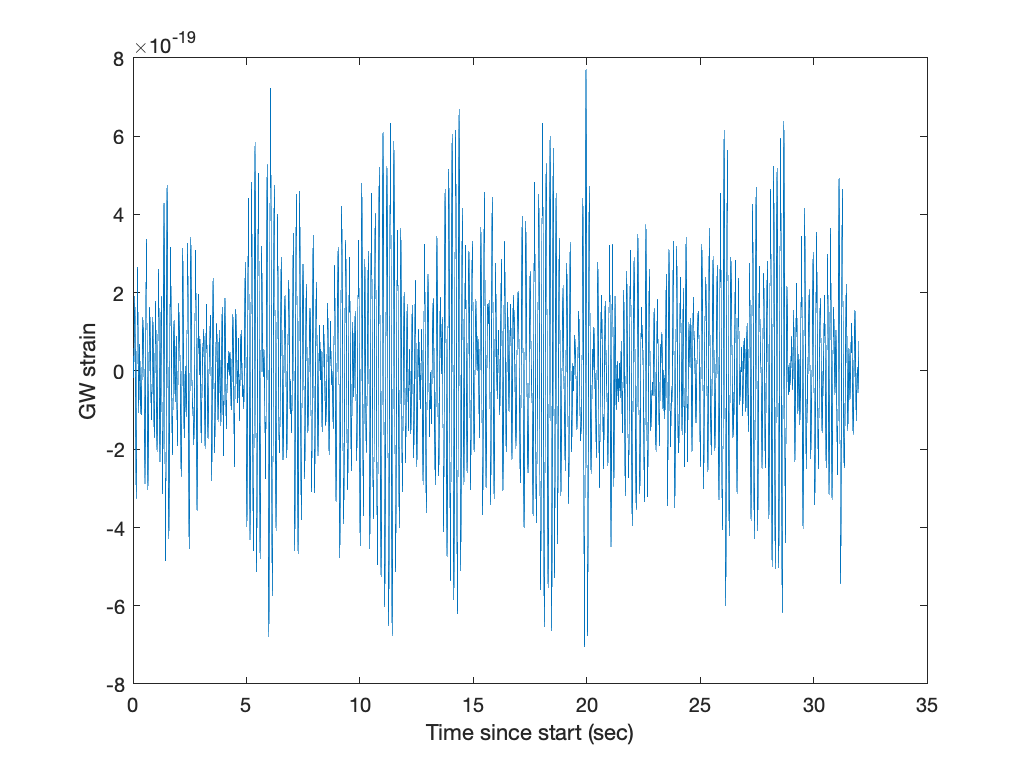

plot(timeVec,dataVec);
xlabel('Time since start (sec)');
ylabel('GW strain');